clear
clf
format compact
load('mnistg_train.mat','mnistg_train')
DB = double(mnistg_train);
[nTrain,cols] = size(DB);
DB(:,2:cols) = DB(:,2:cols)/255; % [0, 255] -> [0., 1.]
nx = cols-1; % label is not a feature
nC = 10;
DB = round(DB);
eta = 0.5;
nEpochs = 2000;
% split DB into DBt and DBv
split = 0.1;
nSplit = round(split*nTrain);
DBv = DB(1:nSplit,:);           % first part of DB into DBv
[nValid , col] = size(DBv);
DBt = DB(nSplit+1:nTrain,:);  % rest of DB inot DBt
[nTrain , col] = size(DBt);

y = zeros(nC,nTrain);
for i = 1:nTrain
    y(DBt(i,1)+1,i)=1;
end

DBt = DBt(:,2:nx+1)';
wM = randn(nx,nC)*0.01; 
bV = randn(nC,1)*0.01;

for epoch = 1:nEpochs
    Z = wM' * DBt + bV;
    A = (1+exp(1).^-Z).^-1;
    dZ = A - y; 
    dw = 1/nTrain*DBt*dZ';
    db = 1/nTrain*sum(dZ,2); 
    wM = wM - eta*dw;
    bV = bV - eta*db;
end

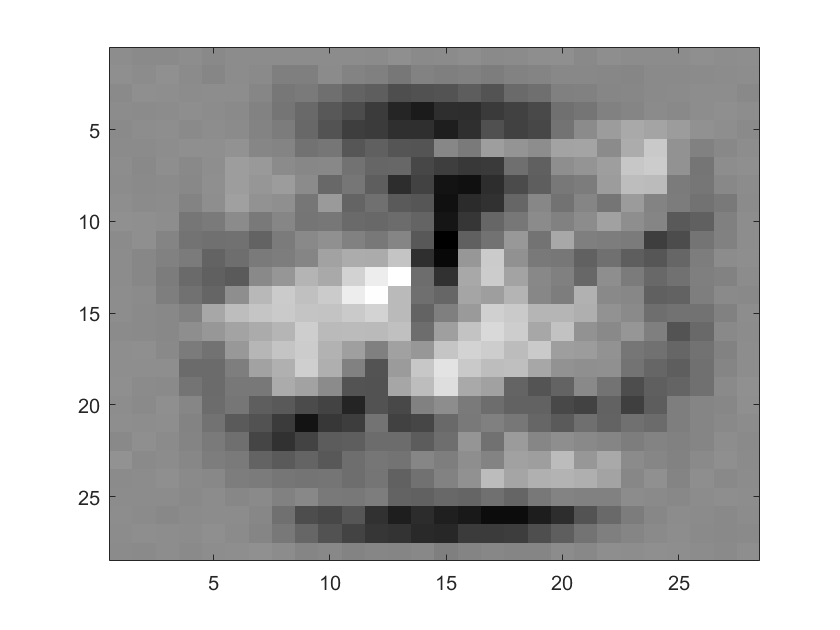

clf
w0 = wM(:,5);
w0 = w0 - min(w0);
w0 = w0/max(w0);
w0 = uint8(255*w0);
Image = reshape(w0, [28 28]);
colormap(gray)
imagesc(Image')

Nerr = 0;
for i = 1:size(DBv,1)
    sample = DBv(i,2:785);
    label = DBv(i,1);
    result = sample * wM + bV';
    result = (1+exp(1).^-result).^-1;
    [val,loc] = max(result);
    if loc-1 ~= label     % [1,10] -> [0,9]
            Nerr = Nerr+1;
    end
end
PE = Nerr/size(DBv,1)

PE = 0.0868

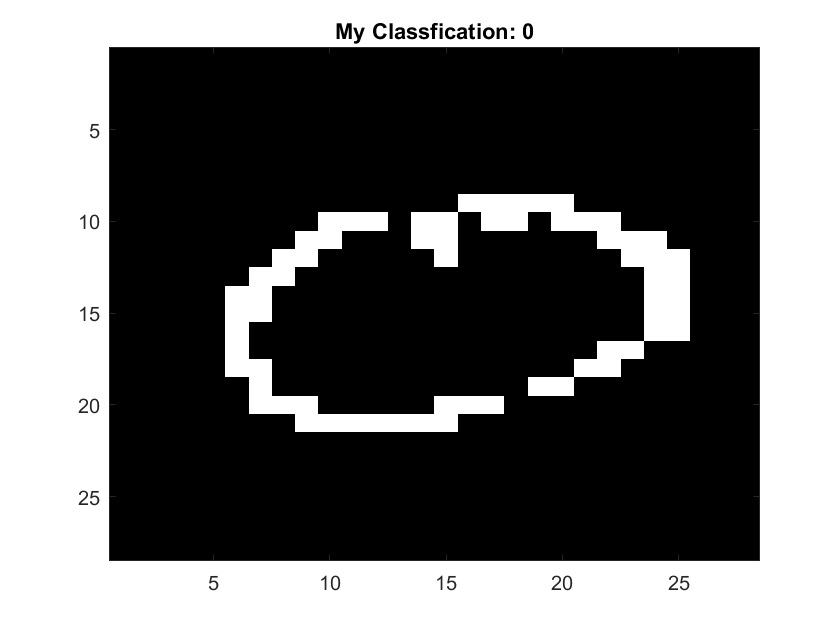

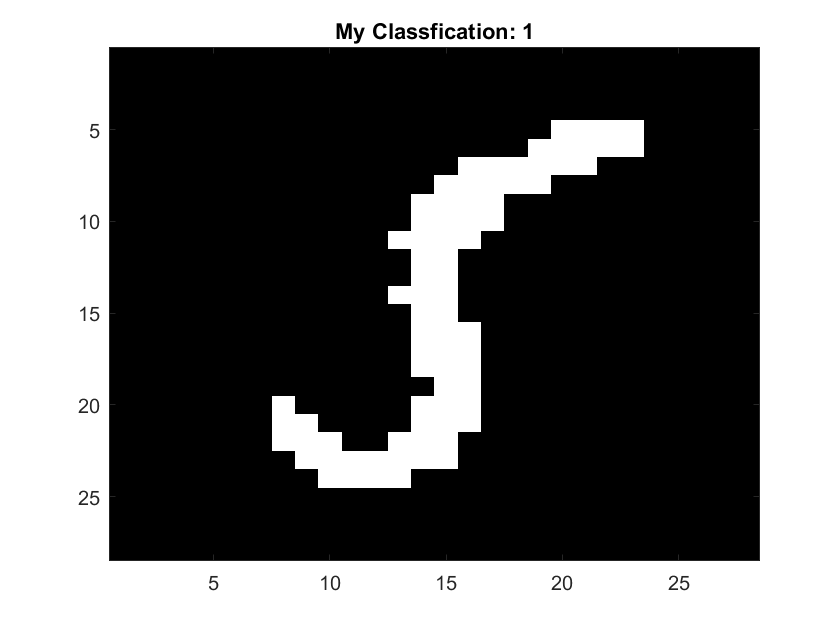

clf
cont = 1;
while true
    i = randi(size(DBv,1));
    sample = DBv(i,2:785);
    label = DBv(i,1);
    result = sample * wM + bV';
    result = 1+exp(1).^-result;
    result = result.^-1;
    [val,loc] = max(result);
    Image = reshape(sample, [28 28]);
    imagesc(Image')
    colormap(gray)
    str = ['My Classfication: ' num2str(loc-1)];
    title(str)
    cont = input("continue?");
    if cont ~= 1
        break
    end
    clf
end

save('mnistg10_weights','wM','bV');